# IMPORTANT: BEFORE YOU START!

Do **NOT** click on the green run button!

Execute this script by stepping section to section, read instructions and inspect results.

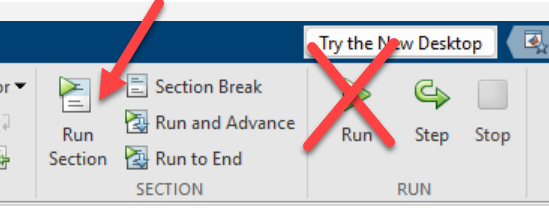

Before you start with the exercises, let's add the folder with the files and solutions required to complete each step.

close all;
clear all;
bdclose all;
clc;

addpath('./Solutions')
addpath('./Files')

## Exercise 5: Design a phase shifter and combine it on the PCB with the Wilkinson combiner

Number of steps: 6

Expected completion time: 20 minutes

In the previous step you determined that a 90 degrees was required to combine the two outputs from the antenna. In this step, you build the phase shifter using a distributed PCB element, and combine it on the PCB together with the Wilkinson splitter. You use EM analysis to determine the S-parameters and integrate them in the system-level model.

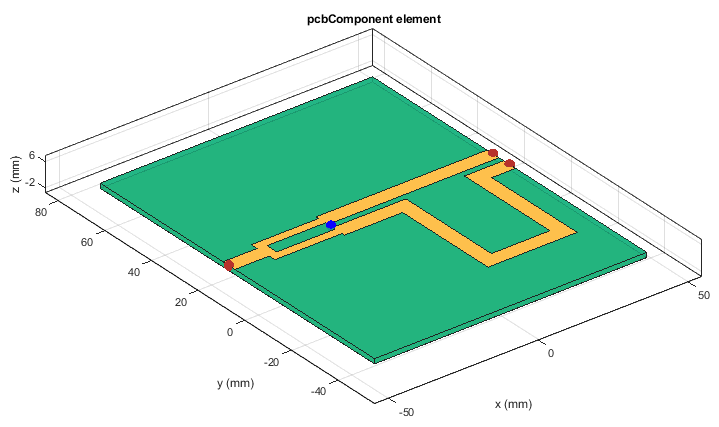

**5.1 Design the **`phaseShifter` catalog element from RF PCB Toolbox to operate at the desired center frequency. 

Compute its S-parameters using EM analysis and verify that the implemented phase shift is 90 degrees.

The phase shifter will be appended on the PCB to one of the branches of the Wilkinson combiner.

phaseShift = design(phaseShifter, 2.45e9);
figure; show(phaseShift);
sparamPhaseShift=sparameters(phaseShift, (2205:24.5:2695)*1e6);
figure; rfplot(sparamPhaseShift,'angle');

**5.2 **To maintain a rectangular shape for the PCB, you need to **design a microstrip line with the same length as the phase shifter**. This allows the other port of the Wilkinson splitter to reach the border of the board.

l1 = phaseShift.PortLineLength;
l2 = phaseShift.SectionShape.Length(2);
w = phaseShift.PortLineWidth;
mLine = microstripLine('Width',w, 'Length',2*(l1+w)+l2);
figure; show(mLine);
sparamLine=sparameters(mLine, (2205:24.5:2695)*1e6);
figure; rfplot(sparamLine,'angle');

**5.3 **Use the graphical interface to **connect port 3 of the Wilkinson splitter with port 1 of the phase shifter**. Save the resulting object to the workspace with the name **pcb**.

pcbcascade(wilkCombiner,phaseShift,'Interactive',true);

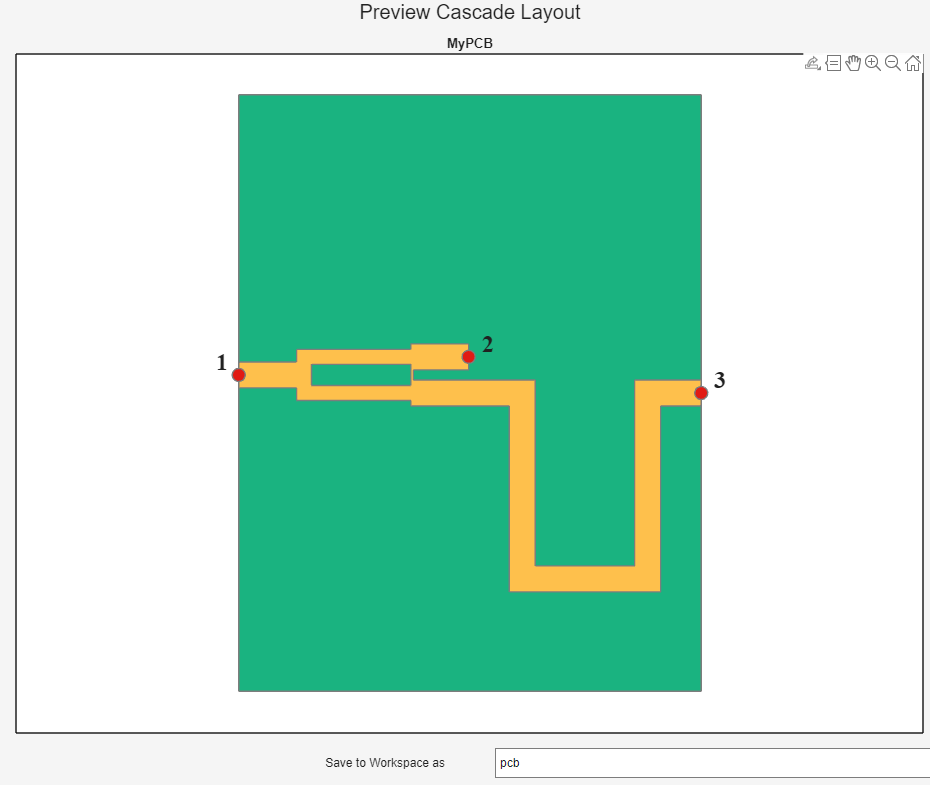

**5.4** Use again the same graphical interface to **connect port 2 of the PCB structure created in the previous step with port 1 of the microstrip line**. Save the resulting object to the workspace with the name **pcb**.

pcbcascade(pcb,mLine,'Interactive',true);

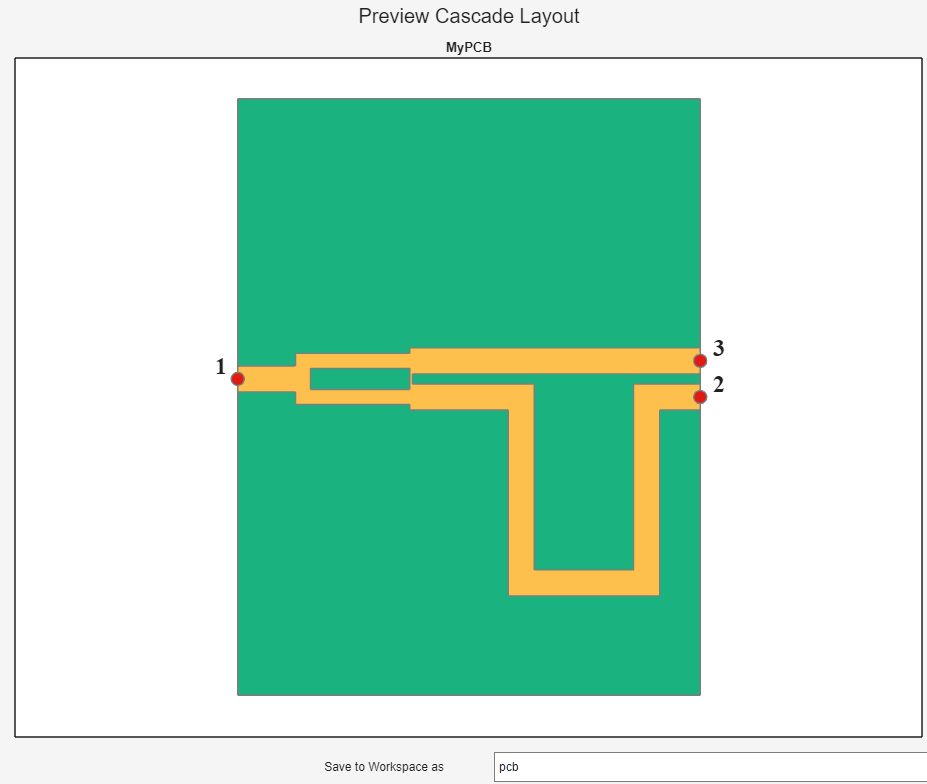

**5.5 **You use EM analysis to compute the S-parameters of the PCB, save them in a Touchstone file. Verify the 90 degrees phase difference along the 2 branches.

sparamWilkSplitterPhaseShift=sparameters(pcb, (2205:24.5:2695)*1e6);
figure; rfplot(sparamWilkSplitterPhaseShift,1,2,'angle');
hold on; rfplot(sparamWilkSplitterPhaseShift,1,3,'angle');
rfwrite(sparamWilkSplitterPhaseShift,'wilkinsonSplitterPhaseShiftSparams.s3p')

**5.6 **Open the Simulink testbench below, and inside the direct conversion receiver, **open the the **`RF PCB Wilkinson Splitter`** subsystem**. 

open_system('Exercise4_RFReceiverWithPCB.slx')

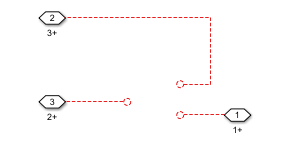

Add an S-parameter block, and specify the Touchstone file `wilkinsonSplitterPhaseShiftSparams.s3p`.

Enable noise generation in the block.

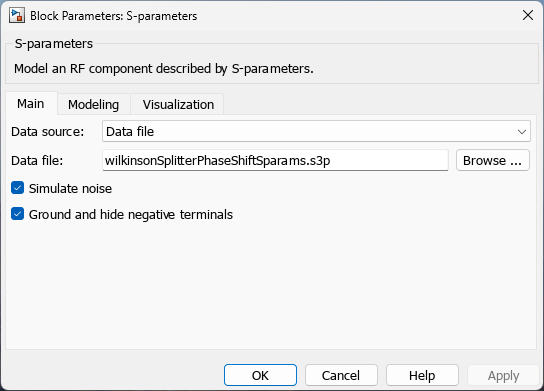

Connect the three port S-parameter block, run the simulation, and verify the ChER to be around 12%.

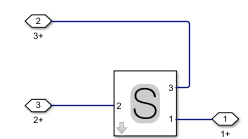

Extra: verify how the additional phase rotation introduced by the combiner / phase offset is accounted for in the baseband receiver and comment about:

- Is the model representative of the actual baseband receiver implementation?

- Would this approach also work for a wideband modulated signal?

**Solution **

Create the PCB integrating the Wilkinson combiner with the phase shift, the microstrip line. Compute the S-parameters and visualize them. Verify phase shifts on both branches as well as the transmission loss.

wilkCombiner=design(wilkinsonSplitter, 2.45e9);
phaseShift = design(phaseShifter, 2.45e9);
l1 = phaseShift.PortLineLength;
l2 = phaseShift.SectionShape.Length(2);
w = phaseShift.PortLineWidth;
mLine = microstripLine('Width',w, 'Length',2*(l1+w)+l2);
wilkSplitterPhaseShift = pcbcascade(wilkCombiner,phaseShift,3,1); 
wilkSplitterPhaseShift = pcbcascade(wilkSplitterPhaseShift,mLine,2,1); 
figure; show(wilkSplitterPhaseShift);
sparamWilkSplitterPhaseShift=sparameters(wilkSplitterPhaseShift, (2205:24.5:2695)*1e6);
figure; rfplot(sparamWilkSplitterPhaseShift,1,2,'angle');
hold on; rfplot(sparamWilkSplitterPhaseShift,1,3,'angle');
figure; rfplot(sparamWilkSplitterPhaseShift,1,2);
rfwrite(sparamWilkSplitterPhaseShift,'wilkinsonSplitterPhaseShiftSparams.s3p')

Open the resulting integrated model:

open_system('Solution4_RFReceiverWithPCB.slx')

The model is not representative of the actual baseband receiver implementation, as the relative phase shift is normally recovered by means of an adaptive clock and phase recovery system.

In this simple model, this approach could be used as the signal phase offset is constant and only dependent on the dispersive components in the chain. In case of a wideband modulated signal though the phase shift would be frequency dependent, and the receiver would require an adaptive equalizer. 

The implemented phase shift of 115 degrees has been determined by inspecting the phase rotation in the budget analysis.

rfBudgetAnalyzer('rfbudget_RFReceiverXdipole.mat') 

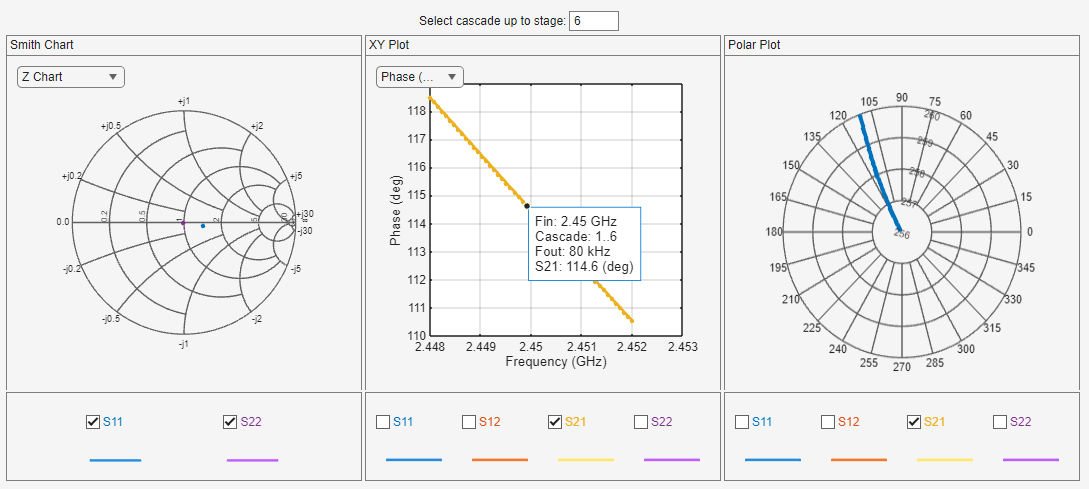

**Exercise outcome and summary**

In this exercise, you learned how to design distributed PCB components and integrate frequency-dependent S-parameters into your system-level testbench.

## Conclusion

Following a top-down design methodology, you designed and analyzed the budget of an RF receiver using component specifications. After integrating an antenna, the impact of an interfering signal including polarization mismatch was simulated. A dual polarized antenna and the PCB feed network was integrated to increase modeling fidelity. The design was validated at each stage to confirm that the overall system performance goals were achieved.

*Copyright 2018-2024 The MathWorks, Inc.*